clearvars
close all
clc

Chargement du fichier tdms (on peut aussi utiliser uigetfile pour choisir le fichier)

%file=uigetfile('.tdms');
file='09-10-2024T09-34-36-733480_P1_N1_Burst_1.tdms';

Pour connaitre tous les paramètres du fichier, on utilise la fonction tdmsinfo

info=tdmsinfo(file)

info =   TdmsInfo with properties:

           Path: "C:\Users\baptiste.menetrier\Desktop\devPy\phd\real_data_analysis\fiberscope\09-10-2024T09-34-36-733480_P1_N1_Burst_1.tdms"
           Name: "Temporaire"
    Description: ""
          Title: ""
         Author: ""
        Version: "2.0"
    ChannelList: [11×8 table]


La liste des canaux est un tableau de 10 lignes sur 8 colonne. Pour connaitre les champs, on affiche info.ChannelList

On voit que les 5 premières lignes sont des données de type "acquisition hydro - données" et qu'elles contiennent 1040000 échantillons (NumSamples)

info.ChannelList

ans = 11×8 table
    ChannelGroupNumber              ChannelGroupName               ChannelGroupDescription    ChannelName    ChannelDescription      Unit       DataType     NumSamples
    __________________    _____________________________________    _______________________    ___________    __________________    _________    _________    __________

            1             "Acquisition Hydros - Données"                     ""                "Hydro1"          ""                "Volts"      "Double"      2920000  
            1             "Acquisition Hydros - Données"                     ""                "Hydro2"          ""                "Volts"      "Double"      2920000  
            1             "Acquisition

En sélectionnant le type de données "Acquisition hydros - données" et le canal Hydro 1, on peut obtenir les propriétés de la donnée, en particulier son pas temporel wf_increment en seconde.

proprietes=tdmsreadprop(file, "ChannelGroupName","Acquisition Hydros - Données", "ChannelName", "Hydro1")

proprietes = 1×17 table
      name      NI_Scaling_Status    NI_Number_Of_Scales    NI_Scale[1]_Scale_Type    NI_Scale[1]_Polynomial_Coefficients_Size    NI_Scale[1]_Polynomial_Coefficients[0]    NI_Scale[1]_Polynomial_Coefficients[1]    NI_Scale[1]_Polynomial_Coefficients[2]    NI_Scale[1]_Polynomial_Coefficients[3]    NI_Scale[1]_Polynomial_Input_Source    NI_ChannelName    unit_string    NI_UnitDescription            wf_start_time            wf_increment    wf_start_offset    wf_samples
    ________    _________________    ___________________    ______________________    ________________________________________    <

pas_temp=proprietes.wf_increment % incrément des données en seconde

pas_temp = 5.0000e-06

Fe=1/pas_temp

Fe = 2.0000e+05

pas_temp

pas_temp = 5.0000e-06

seconds(pas_temp)

ans = duration
   5e-06 sec


file

file = '09-10-2024T09-34-36-733480_P1_N1_Burst_1.tdms'

Lecture des données : on lit les données grâce à tdmsread et on fixe la datation avec seconds(pas), cela transforme la variable pas qui est une donnée numérique double en valeur timetable.

data=tdmsread(file,TimeStep=seconds(pas_temp));

Invalid argument at position 3. Value must be a scalar.

Les valeurs des signaux sont dans la première boite de data. 

matrice_data=data{1};

la variable matrice_data de type timetable contient- 1 colonne de temps Time et 5 colonnes : Hydro1, Hydro2, ..., Hydro5

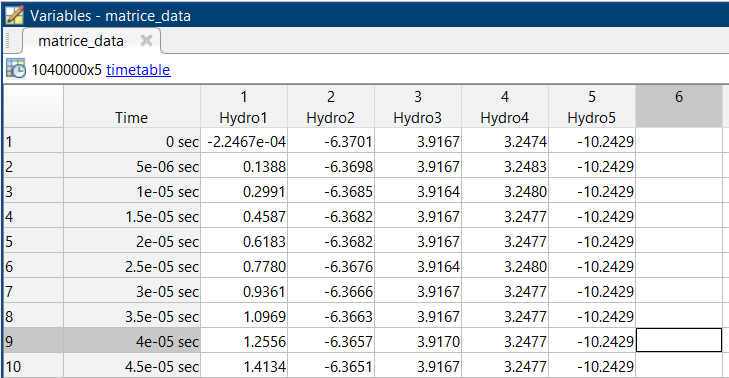


temps=matrice_data.Time;
hydro1=matrice_data.Hydro1;
hydro2=matrice_data.Hydro2;
hydro3=matrice_data.Hydro3;
hydro4=matrice_data.Hydro4;
hydro5=matrice_data.Hydro5;

figure
plot(temps, hydro1)
title('hydro1')
xlim([seconds(0) seconds(6e-3)])
%figure
%stackedplot(matrice_data) % représente les graphes 

figure
subplot(321)
plot(temps, hydro1)
title('hydro1')
subplot(322)
plot(temps, hydro2)
title('hydro2')
subplot(323)
plot(temps, hydro3)
title('hydro3')
subplot(324)
plot(temps, hydro4)
title('hydro4')
subplot(325)
plot(temps, hydro5)
title('hydro5')

Traitement en fréquentiel

N=length(hydro1);
spectre=fftshift(fft(hydro1))/N;
freq=linspace(-Fe/2, Fe/2-Fe/N, N);

figure
plot(freq,abs(spectre))
%xlim([-10e3 10e3])
zoom

grid on
